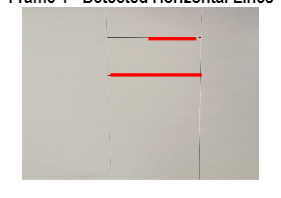

clc; clear; close all;

% Load two consecutive images
image1 = imread('Trial_Image_1.jpg');
image2 = imread('Trial_Image_2.jpg');

% Convert to grayscale
gray1 = rgb2gray(image1);
gray2 = rgb2gray(image2);

% Apply Gaussian Blur
blurred1 = imgaussfilt(gray1, 2);
blurred2 = imgaussfilt(gray2, 2);

% Apply Canny Edge Detection
edges1 = edge(blurred1, 'Canny');
edges2 = edge(blurred2, 'Canny');

% Apply Hough Transform
[H1, theta1, rho1] = hough(edges1);
[H2, theta2, rho2] = hough(edges2);

% Detect peaks in Hough Transform
peaks1 = houghpeaks(H1, 10);
peaks2 = houghpeaks(H2, 10);

% Extract line segments
lines1 = houghlines(edges1, theta1, rho1, peaks1, 'FillGap', 10, 'MinLength', 50);
lines2 = houghlines(edges2, theta2, rho2, peaks2, 'FillGap', 10, 'MinLength', 50);

% Filter only horizontal lines (angle close to 0 degrees)
horizontalLines1 = filterHorizontalLines(lines1);
horizontalLines2 = filterHorizontalLines(lines2);

% Sort lines by vertical position (Y-coordinates)
horizontalLines1 = sortrows(horizontalLines1, 1); % Sort by Y1
horizontalLines2 = sortrows(horizontalLines2, 1); % Sort by Y1


% Match lines based on closest Y-coordinates
[matchedY1, matchedY2] = matchLines(horizontalLines1, horizontalLines2);

% Calculate displacement (Δy = y_new - y_old)
displacements = matchedY2 - matchedY1;

% Calculate displacement (Δy = y_new - y_old)
%displacements = horizontalLines2(:, 1) - horizontalLines1(:, 1);

% % Display results
% figure;
% imshow(image1); hold on;
% drawLines(horizontalLines1, 'r'); % Red for frame 1
% title('Frame 1 - Detected Horizontal Lines');
% 
% figure;
% imshow(image2); hold on;
% drawLines(horizontalLines2, 'g'); % Green for frame 2
% title('Frame 2 - Detected Horizontal Lines');
% 
% % Display displacement
% disp('Displacement of horizontal lines (Δy):');
% disp(displacements);
% 
% % Function to filter only horizontal lines
% function filteredLines = filterHorizontalLines(lines)
%     filteredLines = [];
%     for k = 1:length(lines)
%         xy = [lines(k).point1; lines(k).point2];
%         angle = atan2d(xy(2,2) - xy(1,2), xy(2,1) - xy(1,1)); % Angle in degrees
% 
%         if abs(angle) < 5 % Select near-horizontal lines
%             filteredLines = [filteredLines; xy(1,2), xy(1,1), xy(2,2), xy(2,1)];
%         end
%     end
% end
% 
% % Function to draw lines on an image
% function drawLines(lines, color)
%     for k = 1:size(lines, 1)
%         plot([lines(k, 2), lines(k, 4)], [lines(k, 1), lines(k, 3)], color, 'LineWidth', 2);
%     end
% end
% 

% Display results
figure;
imshow(image1); hold on;
drawLines(horizontalLines1, 'r'); % Red for frame 1
title('Frame 1 - Detected Horizontal Lines');

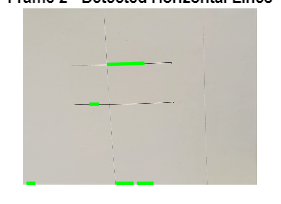


figure;
imshow(image2); hold on;
drawLines(horizontalLines2, 'g'); % Green for frame 2
title('Frame 2 - Detected Horizontal Lines');


% Display displacement
disp('Displacement of horizontal lines (Δy):');

Displacement of horizontal lines (Δy):


disp(displacements);

   131
   139




%% Function to filter only horizontal lines
function filteredLines = filterHorizontalLines(lines)
    filteredLines = [];
    for k = 1:length(lines)
        xy = [lines(k).point1; lines(k).point2];
        angle = atan2d(xy(2,2) - xy(1,2), xy(2,1) - xy(1,1)); % Angle in degrees
        
        if abs(angle) < 5 % Select near-horizontal lines
            filteredLines = [filteredLines; xy(1,2), xy(1,1), xy(2,2), xy(2,1)];
        end
    end
end

%% Function to match lines based on closest Y-coordinates
function [matchedY1, matchedY2] = matchLines(lines1, lines2)
    y1_vals = lines1(:, 1); % Y-coordinates of frame1
    y2_vals = lines2(:, 1); % Y-coordinates of frame2
    
    matchedY1 = [];
    matchedY2 = [];
    
    for i = 1:length(y1_vals)
        [~, idx] = min(abs(y2_vals - y1_vals(i))); % Find closest Y in frame2
        if ~isempty(y2_vals)
            matchedY1 = [matchedY1; y1_vals(i)];
            matchedY2 = [matchedY2; y2_vals(idx)];
            
            % Remove matched value to prevent duplicates
            y2_vals(idx) = [];
        end
    end
end

%% Function to draw lines on an image
function drawLines(lines, color)
    for k = 1:size(lines, 1)
        plot([lines(k, 2), lines(k, 4)], [lines(k, 1), lines(k, 3)], color, 'LineWidth', 2);
    end
end